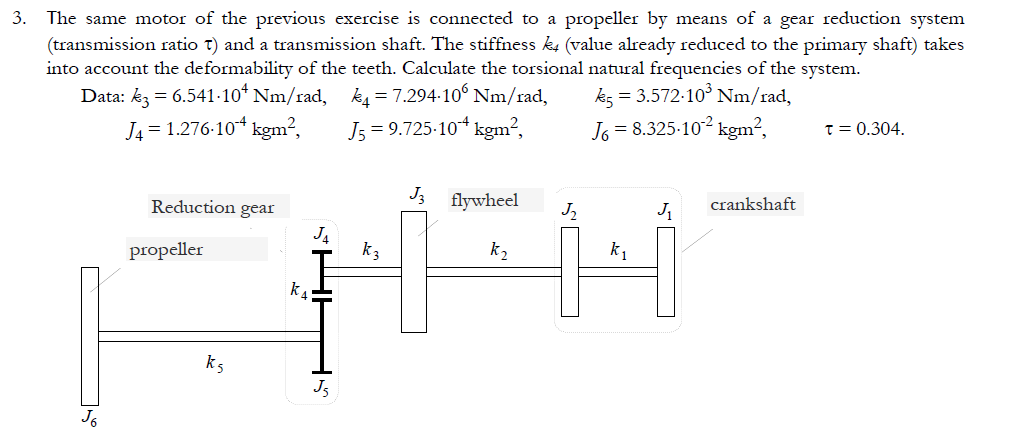

clear 
clc
tau=.304;
leq=149.5e-3;
D=30e-3;
d=10e-3;
G=7.7e10;
k2=5.29e4;
J1=4.647e-3;
J2=J1;
J3=4.98e-2;

k3=6.541e4;
k4=7.294e6;
k5=3.572e3*tau^2;
J4=1.276e-4;
J5=9.275e-4*tau^2;
J6=8.325e-2*tau^2;


% Since tau<1, it is defined as Omega5/Omega4, but we should use
% tau=Omega4/Omega5 , hence:
tau=1/tau;

Ip=pi*(D^4-d^4)/32;
k1=G*Ip/leq;

% k4 is arealdy reduced to the primary shaft
k_4=k4;
k_3=k3;
k_2=k2;
k_1=k1;
J_4=J4;
J_3=J3;
J_2=J2;
J_1=J1;

K=[k5   -k5     0       0       0       0
   -k5  k5+k_4  -k_4    0       0       0
   0    -k_4    k_4+k_3 -k_3    0       0
   0    0       -k_3    k_3+k_2 -k_2    0
   0    0       0       -k_2    k_2+k_1 -k_1
   0    0       0       0       -k_1    k_1];

M=[J6   0     0     0     0    0
   0    J5    0     0     0    0
   0    0     J_4   0     0    0
   0    0     0     J_3   0    0
   0    0     0     0     J_2  0
   0    0     0     0     0    J_1];

[phi,w]=eig(K,M);

wt=sqrt(w);

% The first natural frequency is zero due to rigid body motion (rotation)
disp(' Torsional natural frequencies[rad/s]:')

 Torsional natural frequencies[rad/s]:


disp(' ')

for i=2:6
disp(wt(i,i))
end

  219.5889

   2.1602e+03

   5.0185e+03

   1.7580e+04

   3.7745e+05

